# Project 5 (Sports Performance Analystics)

%{
Analyze performance statistics
   originally from ES115 Engineering Computer Applications, Module 3
   project bank, project 19
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   -
%}

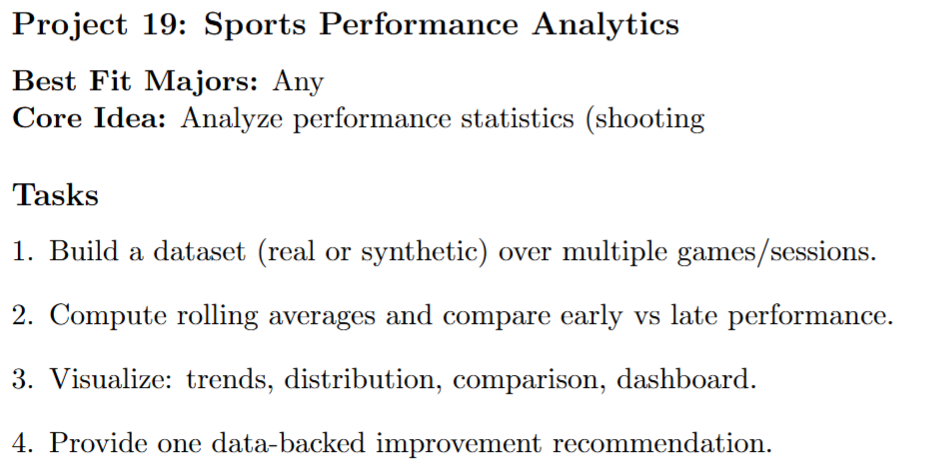

clc
clear

% define the variables
load('uswnt.csv') % loads the data
Game = uswnt(:, 1); % defines game from the data
SAvgAge = uswnt(:, 2); % defines average age from the data
SAvgCaps = uswnt(:, 3); % defines average number of international appearances from the data
sGoals = uswnt(:, 4); % defines goals scored from the data
oppGoals = uswnt(:, 5); % defines opponent goals scored from the data
subs = uswnt(:, 6); % defines number of substitutions from the data
WinLoss = uswnt(:, 7); % defines number of win from the data
shots = uswnt(:, 8); % defines number of shots on goal from the data

% creates a table containing the data
disp('2025 U.S. Womens National Soccer Team Data') % acts as a title for the table

2025 U.S. Womens National Soccer Team Data


table(Game, SAvgAge, SAvgCaps, sGoals, oppGoals, subs, WinLoss, shots) % creates a table of the data

ans = 15×8 table
    Game    SAvgAge    SAvgCaps    sGoals    oppGoals    subs    WinLoss    shots
    ____    _______    ________    ______    ________    ____    _______    _____

      1      26.23       27.77       2          0         5         1         4  
      2      24.54       20.55       2          1         6         1         6  
      3       26.9       33.55       1          2         6         0         5  
      4      26.73       36.47       2          0         6         1        13  
      5      23.16       14.02       1          2         7         0         3  
      6      25.77       30.69       3          0         6         1        20  
      7      24.03       14.81       4          0     

% averages from the data
AgeM = mean(SAvgAge); % finds the average player age across all the games
CapsM = mean(SAvgCaps); %finds average number of appearances across all the games
fprintf('Average player age: %g years', AgeM) % displays the average age

Average player age: 24.7729 years

fprintf('Average number of international appearances per player: %g', CapsM) % displays the average appearances

Average number of international appearances per player: 22.0451

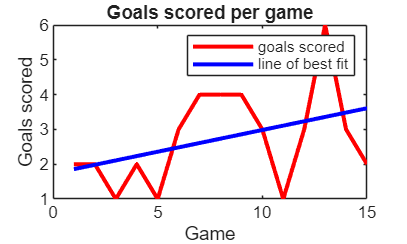

% a plot of goals vs game
plot(Game, sGoals, 'r-', 'LineWidth',2) % makes the line red with a width of 2
title('Goals scored per game') % creates a title for the graph
xlabel('Game') % labels the x axis as game
ylabel('Goals scored') % labels the y axis as goals scored
hold on % allows for something else to be plotted on the same graph
p = polyfit(Game, sGoals, 1); % find a slope and intercept for a line of best fit
yfit = polyval(p, Game); % creates a line of best fit
plot(Game, yfit, 'b-', 'LineWidth', 2) % plots the line of best fit
hold off % finishes graphing on this plot
legend('goals scored', 'line of best fit') % creates a legend to distinguish between the lines

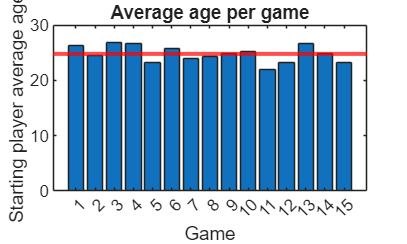

% creates a bar graph to represent average player age in each game
bar(Game, SAvgAge) 
title('Average age per game') % titles the bar graph
xlabel('Game') % labels the x axis game
ylabel('Starting player average age') % labels the y axis 
yline(AgeM, 'r-', 'LineWidth', 2) % creates a line on plot to represent the average age across all games

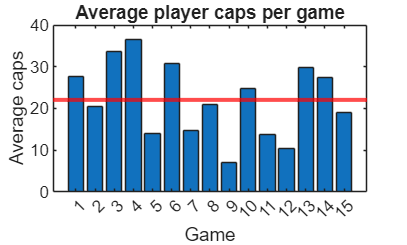

% creates a bar graph to represent average player caps for each game
bar(Game, SAvgCaps)
title('Average player caps per game') % titles the graph
xlabel('Game') % labels the x axis game
ylabel('Average caps') % labels the y axis average caps
yline(CapsM, 'r-', 'LineWidth', 2) % creates a line to represent average caps for all games in the 2025 season

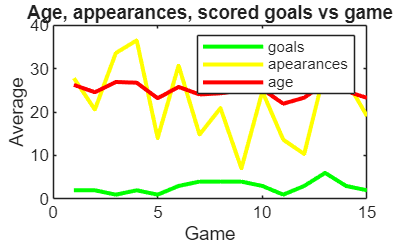

% avg age, avg caps vs goals (same plot)
figure
plot(Game, sGoals, 'g-', 'LineWidth', 2)
hold on
plot(Game, SAvgCaps, 'y-', 'LineWidth',2)
plot(Game, SAvgAge, 'r-', 'LineWidth', 2)
hold off
title('Age, appearances, scored goals vs game')
xlabel('Game')
ylabel('Average')
legend('goals', 'apearances', 'age')

% plot win vs average number of appearances

% Calculate win percentage
winPercentage = sum(WinLoss) / length(WinLoss) * 100;
fprintf('Win percentage: %.2f%%\n', winPercentage); % displays the win percentage

Win percentage: 80.00%


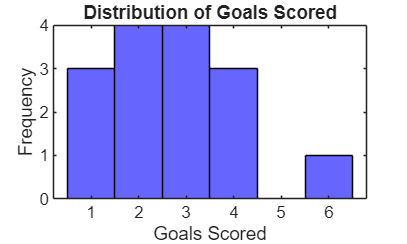

% creates a histogram with goals 
figure
histogram(sGoals, 'FaceColor', 'b', 'EdgeColor', 'k')
title('Distribution of Goals Scored')
xlabel('Goals Scored')
ylabel('Frequency')

% Create a summary table for wins and goals
summaryTable = table(Game, sGoals, WinLoss);
disp('Summary of Wins and Goals');

Summary of Wins and Goals


disp(summaryTable);

    Game    sGoals    WinLoss
    ____    ______    _______

      1       2          1   
      2       2          1   
      3       1          0   
      4       2          1   
      5       1          0   
      6       3          1   
      7       4          1   
      8       4          1   
      9       4          1   
     10       3          1   
     11       1          0   
     12       3          1   
     13       6          1   
     14       3          1   
     15       2          1   



% improvement recommendation
disp('The number of goals scored is higher on average when the average number of international appearances for the players is higher.')

The number of goals scored is higher on average when the average number of international appearances for the players is higher.


disp('Going into the World Cup, the team should field the players with more appearances.')

Going into the World Cup, the team should field the players with more appearances.


disp('For long-term, they should focus on getting the players with fewer appearances more experience, as they perform better when there is a high average number of appearances.')

For long-term, they should focus on getting the players with fewer appearances more experience, as they perform better when there is a high average appearances.
